# STATISTICAL MODELS: LAB 4

**Members**:

- Luca Franceschi (u199149)

- Marina Castellano (u188311)

- Paula Ceprián (u198630)

% path from MATLAB CURRENT FOLDER to files
dir_prefix = 'resampling/lab4/';

## FUNCTIONS

function corr = correlation_coeff(data)
    % Get shape of the data
    n = size(data, 1);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);

    % Compute correlation coefficient
    num = q * (ordered_data - mean(ordered_data, 1));
    denom1 = diag((ordered_data - mean(ordered_data, 1))' * (ordered_data - mean(ordered_data, 1)))';
    denom2 = q * q';
    
    corr = num ./ sqrt(denom1 .* denom2);
end

function corr = qq_plot(data)
    % Get shape of the data
    [n, dims] = size(data);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);
    
    figure
    set(gcf,'position',[0,0,2000,1000]);

    corr = correlation_coeff(data);
    
    % Draw the corresponding QQ-Plots with regression line
    for i=1:dims
        % Create subplot
        subplot(ceil(sqrt(dims)),floor(sqrt(dims)), i);

        % Scatter plot and regression line in each axis
        scatter(q, ordered_data(:, i));
        hold on;
        b = [ones(n, 1) q']\ordered_data(:,i);
        ycalc = [ones(n, 1) q']*b;
        plot(q, ycalc);

        % Display correlation coefficient too
        y = (ordered_data(end,i)-ordered_data(1,i))*0.1 + ordered_data(1,i);
        text(q(end), y, ['\rho: ' num2str(corr(i))]);
        hold off;

        % Set title and labels for each axis
        title(['QQ-Plot for dim=' num2str(i)]);
        xlabel('Standard normal quantiles');
        ylabel(['Dim=' num2str(i) ' Quantiles']);
    end
end

function corr = retrieve_qq_critical(table, n, alpha)
    cols = [NaN 0.01 0.05 0.1]; % table is formatted this way to make it easier
    col = ismember(cols, alpha);
    if ~any(col)
        error 'Invalid confidence level. Allowed ones are {0.01, 0.05, 0.1}'
    end

    if any(ismember(table{:, 'n'}, n))
        % disp('Entry exists');
        corr = table{table{:, 'n'} == n, :}(col);
    elseif n > 300
        disp('Too large n. Will approximate to n=300');
        corr = table{table{:, 'n'} == 300, :}(col);
    else
        % disp('Entry does not exist, performing linear interpolation');
        lowerBound = table{table{:, 'n'} < n, :}(end,:);
        upperBound = table{table{:, 'n'} > n, :}(1,:);
        corr = linspace(lowerBound(col), upperBound(col), upperBound(1)-lowerBound(1));
        corr = corr(n-lowerBound(1)+1);
    end
end

function detect_outliers(data, alpha)
    p = size(data, 2);
    sample_mean = mean(data);
    cov_matrix = cov(data);

    % Calculate Mahalanobis Distance for each observation
    mahalanobis_dist = sqrt((data-sample_mean) / cov_matrix * (data-sample_mean)');
    
    % Chi-square distribution 
    threshold = chi2inv(1-alpha, p); 
    
    outliers = find(mahalanobis_dist > threshold);
    if any(outliers)
        fprintf('The are outliers');
    else
        fprintf('The are no outliers.')
    end
end

% This function detects how many and deletes the outliers from the data
function cleaned_data = clean_data(data, alpha)
    p = size(data, 2);
    sample_mean = mean(data);
    cov_matrix = cov(data);

    mahalanobis_dist = sqrt(sum(((data - sample_mean) / cov_matrix) .* (data - sample_mean), 2));
    threshold = chi2inv(1 - alpha, p); 
    outliers = mahalanobis_dist > threshold; 
    num_outliers = sum(outliers); 
    
    if num_outliers > 0
        fprintf('There are %d outliers.\n', num_outliers);
    else
        fprintf('There are no outliers.\n');
    end

    cleaned_data = data(~outliers, :); % Keep only rows where outliers are false
end

function resample = boot_resample(X, B, dependency)
    % check input shape
    % dependency is a string that determines if there is any dependency
    %     between the rows of the data (if they have to be sampled by
    %     columns or the links should be broken).
    %     Options: 'dependent' or 'independent
    if ~ismatrix(X)
        error 'boot_resample: The input has unexpected shape'
    end

    [m, n] = size(X);

    if strcmp(dependency, 'independent')
        random_idxs = ceil(rand(m, n, B)*n);
        resample = random_idxs; % init for efficiency
        % sample row-wise differently
        for i=1:m
            resample(i,:,:) = reshape(X(i, random_idxs(i,:,:)), 1, n, B);
        end
    elseif strcmp(dependency, 'dependent')
        resample = reshape(X(:,ceil(rand(B, n)*n)), m, n, B);
    else
        error 'boot_resample: Input parameter 3 (dependency) not recognized'
    end
end

function [ci, corrected_ci] = boot_percentiles_ci(sample_est, resample_est, B, alpha)
    resample_est_ord = sort(resample_est);
    est_low = resample_est_ord(ceil((B+1)*alpha/2));
    est_high = resample_est_ord(ceil((B+1)*(1-alpha/2)));
    ci = [est_low, est_high];
    corrected_ci = [2*sample_est - est_high, 2*sample_est - est_low];
end

function bias = boot_bias(sample_est, resample_est)
    expected_est = mean(resample_est);
    bias = expected_est - sample_est;
end

function se = boot_standard_error(resample_est)
    se = std(resample_est);
end

function [ci, corrected_ci] = boot_studentized_ci(sample_est, bias, se, n, alpha)
    c = tinv(1-alpha/2, n-1);

    ci = [sample_est - c*se, sample_est + c*se];
    corrected_ci = [sample_est - c*se, sample_est + c*se] - bias;
end

function p = p_value(sample_est, resample_est, B, tails)
    resample_est_ord = sort(resample_est);
    if strcmp(tails, 'two-tail')
        count = sum(abs(resample_est_ord) >= abs(sample_est));
    elseif strcmp(tails, 'left-tail')
        count = sum(resample_est_ord <= sample_est);
    elseif strcmp(tails, 'right-tail')
        count = sum(resample_est_ord >= sample_est);
    else
        error 'p_value: Input parameter 4 (tails) not recognized'
    end
    p = (count + 1) / (B + 1);
end

## PROBLEM 1

File *SM23_LabMarks.xlsx *shows the lab marks obtained by the 74 matriculated students in Statistical Models in course 2023-2024. Similarly to the present course, labs 1, 3 and 5 consisted on small exams, while labs 2, 4 and 6 consisted of deliverables. We with to use the data from those 74 students as a random sample to make inferences about the continuous evaluation method that we are using.

More specifically, we wish to assess whether the tests are more difficult than the deliverables, for which we wish to make inferences about the following parameter: 

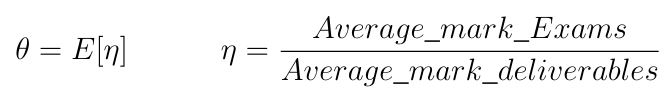

where $E\left\lbrack \right\rbrack$ stands for the expected value. In other words, for each student we are interested in the ratio between his/her average marks on the exams and his/her average marks on the deliverables, which we call $\eta$, and we set the expected value of these ratios as the parameter of the population to be analysed to answer our research question. We will use $\alpha =0\ldotp 05$ as the significance level.

**a) State the null and alternative hypotheses for this problem, including the mathematical formulation in terms of the requested parameter. **

$\begin{cases}
      H_{0}: \theta = 1\\
      H_{A}: \theta < 1\\
\end{cases}$ where $\theta$ is the expected population value of the ratio between exam grades and deliverable grades.

**b) Define a suitable statistic to make inferences about the parameter of interest. Compute this statistic on the provided samples and analyse the obtained values looking for any outliers or invalid data. Be careful with the assumptions that you use (since we expect to use bootstrap in this lab there is no need for normality); justify very well the reasons that allow the exclusion of any data sample in case you decide that this is needed.**

A suitable statistic for this task is the sample mean. The assumptions needed are the following ones:

- TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO 

Since we are using only the averages to compute the needed statistic we will only check if there are outliers in the averages itself, not all its components, using QQ-plots.

% Importing data table for the problem
filename = strcat(dir_prefix, 'SM23_LabMarks.xlsx');
raw = readtable(filename);

% Importing critical values for normality assessment
filename = strcat(dir_prefix, 'qq_plots_critical.csv');
critical_values = readtable(filename);

alpha = 0.05;

deliverable_grades = raw{:,[1 3 5]};
exams_grades = raw{:,[2 4 6]};

deliverables_mean = mean(deliverable_grades, 2, 'omitnan');
exams_mean = mean(exams_grades, 2, 'omitnan');

First of all we will start with the deliverables mean. We will analyze its QQ-plot and we will try to detect outliers.

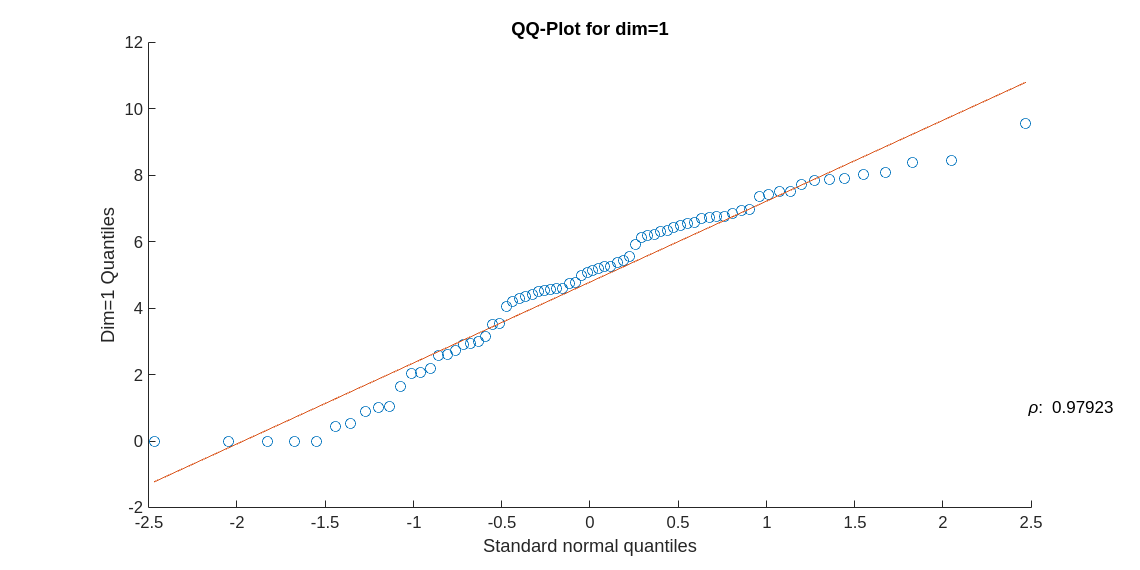

corr = qq_plot(deliverables_mean);

corr

corr = 0.9792

critical_corr = retrieve_qq_critical(critical_values, size(deliverables_mean, 1), alpha);
critical_corr

critical_corr = 0.9838

detect_outliers(deliverables_mean, alpha);

The are no outliers.

From what we can see in the above QQ-plot, the deliverables mean does not follow a normal distribution since the correlation value is smaller than the critical value for the correlation. However there are no outliers.

We will do the same with the exams mean.

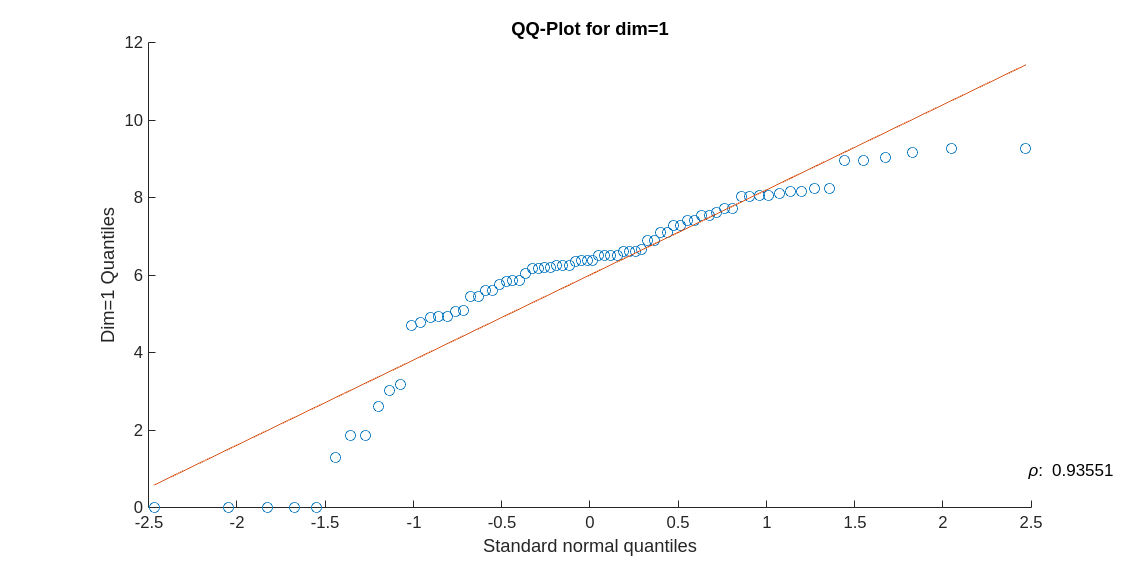

corr = qq_plot(exams_mean);

corr

corr = 0.9355

detect_outliers(exams_mean, alpha);

The are no outliers.

Since there is no need for normality we are not taking into account the (bad) correlation value. We are not detecting any outliers in the averaged data. Maybe in the non-averaged data (labs separately) there are some outliers but we are only taking into account the outliers in the denominator of our needed statistic, that is, the average of labs. The same happens with test means, the normality assumption would not be reached if needed, however we cannot detect outliers.

We conclude that there is no need to exclude any data sample in this step.

**c) Use the sample values computed in (b) to assess whether η is normally distributed.**

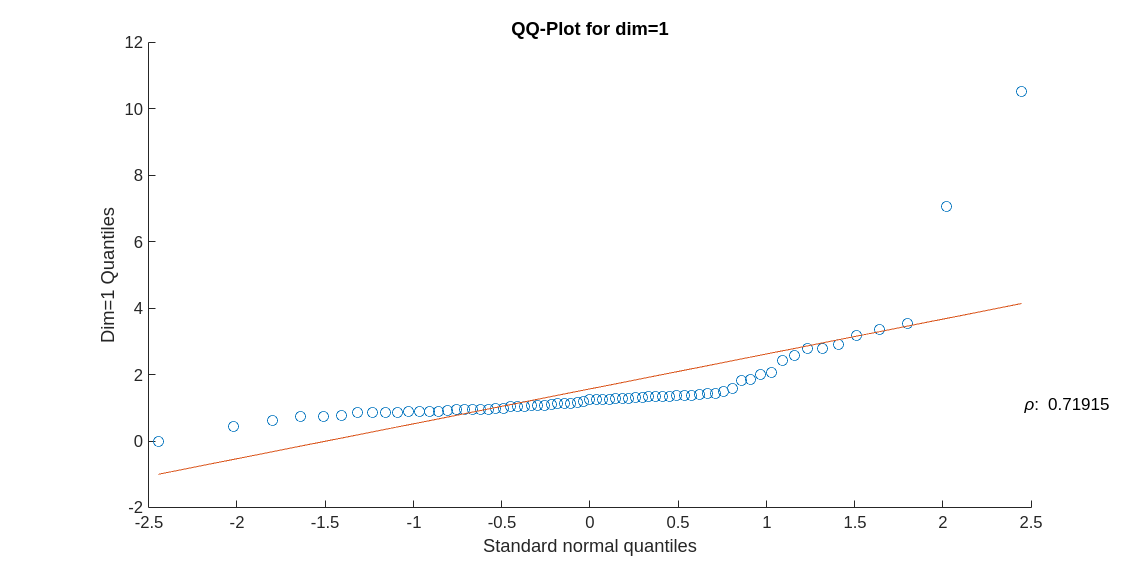

eta = exams_mean ./ deliverables_mean;
eta = eta(~isnan(eta) & ~isinf(eta)); % remove problematic entries

corr = qq_plot(eta);

corr

corr = 0.7192

From what we can see in the above plot the correlation is quite bad (below critical threshold) and we can also see a couple of outliers, however we will need to further analyze those to be sure of removing them. We will analyze also the histograms of values.

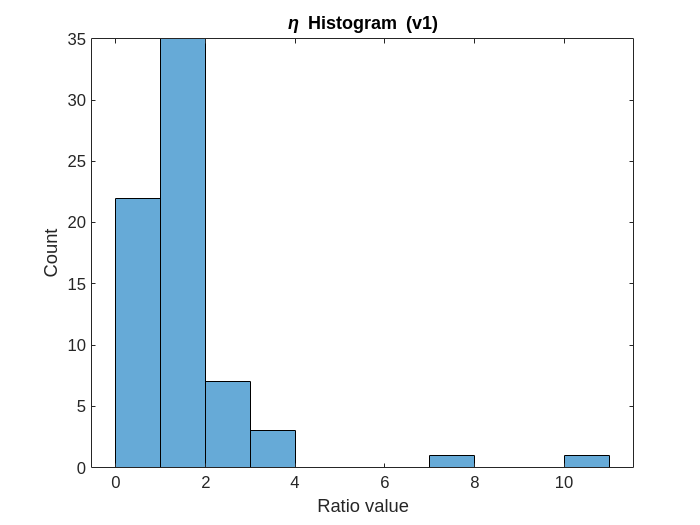

figure;
histogram(eta);
title('\eta Histogram (v1)');
xlabel('Ratio value');
ylabel('Count');

eta = clean_data(eta, alpha);

There are 1 outliers.


detect_outliers(eta, alpha);

The are outliers

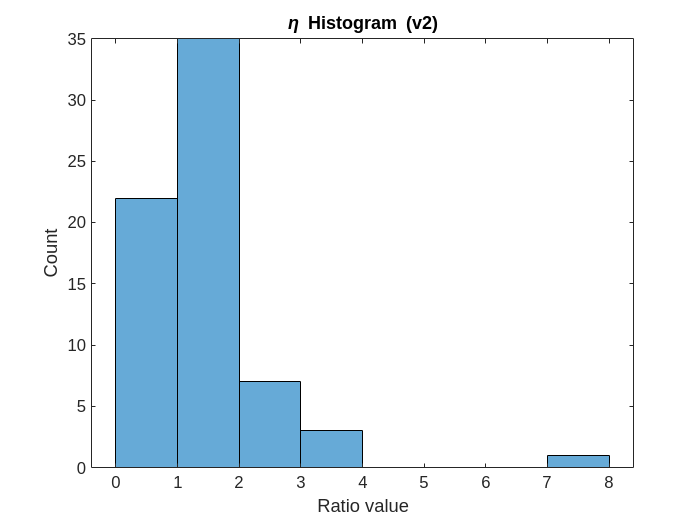

figure;
histogram(eta);
title('\eta Histogram (v2)');
xlabel('Ratio value');
ylabel('Count');

eta = clean_data(eta, alpha);

There are 1 outliers.


detect_outliers(eta, alpha);

The are no outliers.

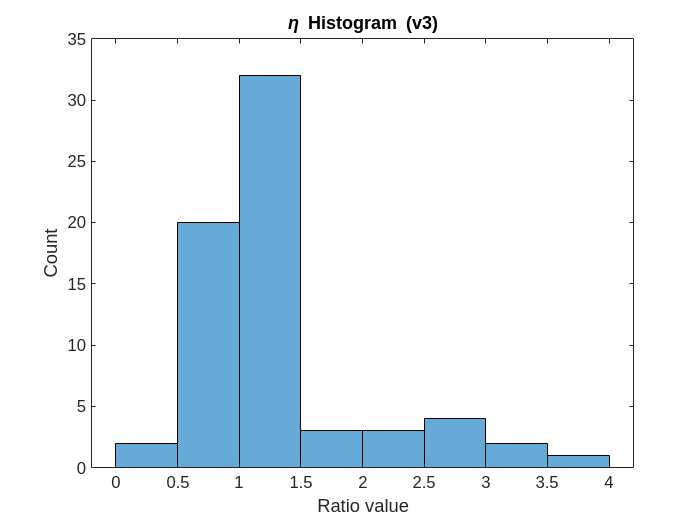

figure;
histogram(eta);
title('\eta Histogram (v3)');
xlabel('Ratio value');
ylabel('Count');

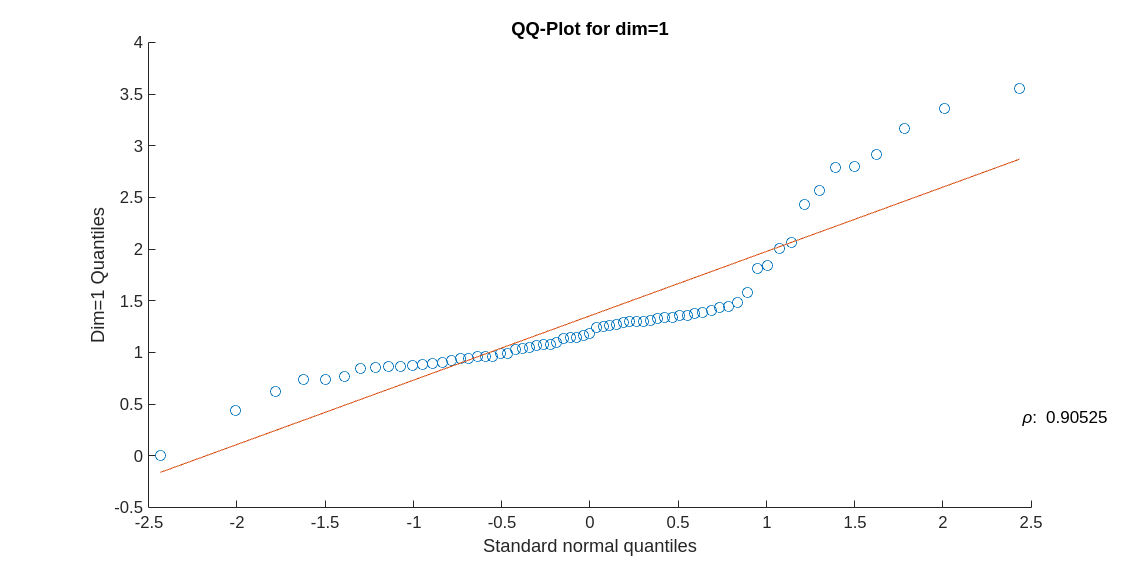

corr = qq_plot(eta);

corr

corr = 0.9052

We can see that there were two outliers (excluding NaN and $\infty$ data). After removing them we can see that the data is still not normal, however we can assure that there are no outliers in the data. Normality should not be a problem since, as stated in problem 1b, there is no need for normality assumption in bootstrap.

**d) Theory suggests that, given the relatively large number of samples, the statistic that you selected in (b) should be normally distributed, regardless of your answer in (c) (Reflect about this and, if you find that it is not the case, then you have most likely chosen a wrong statistic in (b)). Use resampling to confirm whether this holds.**

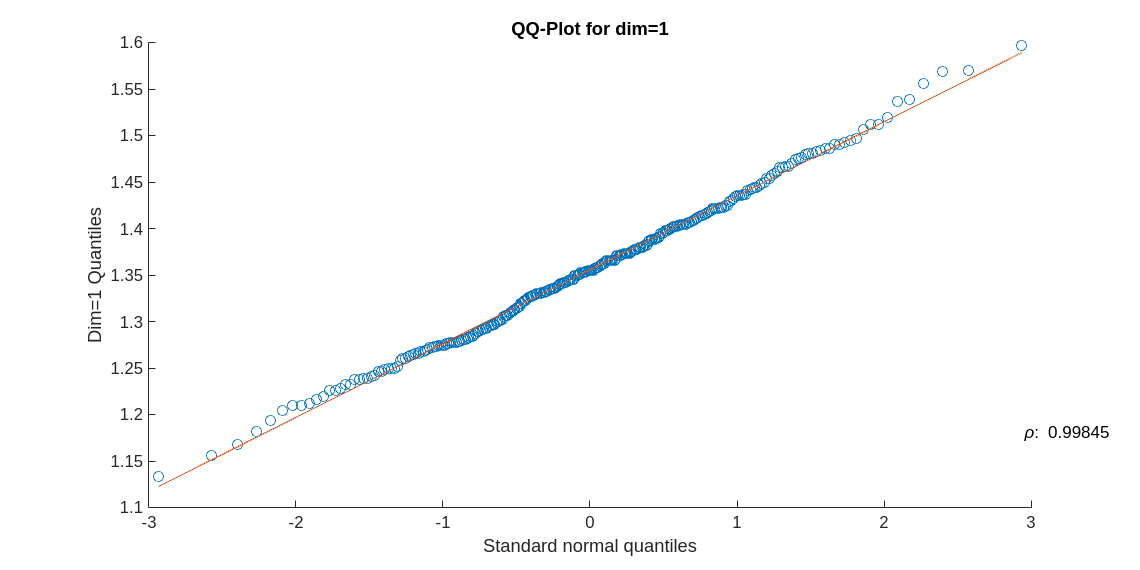

B = 300;

resample = boot_resample(eta', B, 'independent');
resample_est = squeeze(mean(resample, 2));

figure;
corr = qq_plot(resample_est);

corr

corr = 0.9985

critical_corr = retrieve_qq_critical(critical_values, B, alpha);
critical_corr

critical_corr = 0.9953

As expected, we can confirm that after the bootstrap resamples, the statistic $\eta$ is normally distributed. We can see that the QQ-plot follows a straight line and the correlation coefficient is larger than its critical counterpart for a given resample count and confidence level.

Conclusion: $\eta$ (our statistic) is normally distributed.

TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO reflect

**e) Construct an adequate confidence interval for the parameter of interest, in such a way that you can use it to answer our research question. Provide the answer and a clear justification for it.**

sample_est = mean(eta);

[ci, corrected_ci] = boot_percentiles_ci(sample_est, resample_est, B, alpha);
ci

ci =     1.2101    1.5197


corrected_ci

corrected_ci =     1.1909    1.5005


bias = boot_bias(sample_est, resample_est)

bias = 5.0380e-04

se = boot_standard_error(resample_est)

se = 0.0796

We can see that the confidence interval does not contain 1, which means that we can reject our null hypothesis based on the confidence interval. Furthermore we have also computed the corrected confidence intervals in case the bias was high, which for the sample mean statistic should not be the case, since for a high number of resamples bias goes to 0. For B = 300 our bias is shown above, which is not quite high, but still near zero. This is why both confidence intervals are very similar.

As we have concluded that $\eta$ follows a normal distribution, we can also compute the studentized confidence interval based on the standard error and bias of our statistic. We should recall that in this case they should be approximately equal (equal for large N).

[ci, corrected_ci] = boot_studentized_ci(sample_est, bias, se, B, alpha);
ci

ci =     1.1987    1.5119


corrected_ci

corrected_ci =     1.1982    1.5114


**f) Use resampling to test the hypotheses in (a) directly and provide the obtained p-value; compare the result to the one obtained in (e).**

sample_est = mean(eta) - 1;

resample = boot_resample(eta', B, 'independent');
resample_est = squeeze(mean(resample, 2));
p = p_value(sample_est, resample_est, B, 'left-tail');
p

p = 0.0033

## PROBLEM 2

Using the same data used in Problem 1, we wish to address now a different question: are the exam and deliverable marks of students independent? In other words is there a clear relation between the (average) exam and deliverable marks obtained by each student, or they are simply independent because exams and deliverables are so different ways of assessing students?

Again, we will use $\alpha =0\ldotp 05$ as the significance level, and now the parameter of interest will be the correlation coefficient between the average-exam and average-lab marks.

**a) State the null and alternative hypotheses for this problem, including the mathematical formulation in terms of the requested parameter.**

TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO 

**b) Using the sample correlation as your statistic, compute its values using only the samples that you decided to be valid in Problem 1(b). Use resampling to assess whether the chosen statistic follow a normal distribution.**

**c) Construct an adequate confidence interval for the parameter of interest, in such a way that you can use it to answer our research question. Provide the answer and a clear justification for it.**

**f) Use resampling to test the hypotheses in (a) directly and provide the obtained p-value; compare the result to the one obtained in (c).**

## PROBLEM 3

To design clothing, a company selling excercise clothing has collected data on then physical characteristics of customers. File *SM_Lab_4_WeightsRunners.xlsx* provides the weights (kg) for a random sample of 25 male runners. Since products target the average male you are interested in seeing how much the subjects in your sample vary from the average weight.

% Importing data table for the problem
filename = strcat(dir_prefix, 'SM_Lab_4_WeightsRunners.xlsx');
raw = readtable(filename);

**a) Calculate the sample standard deviation** $\mathbf{\hat{\sigma}}$** for these weights and find the bias of **$\mathbf{\hat{\sigma}}$**.**

**b) Use bootstrapping to find the bootstrap standard error for **$\mathbf{\hat{\sigma}}$**.**

**c) Make a histogram of the bootstrap replications of **$\mathbf{\hat{\sigma}}$** from (b). Inspect the data to try assessing why do we obtain such a strange histogram.**

**d) Suggest a way to improve the analysis so that you can compute a confidence interval using bootstrapping. Clearly justify why your proposal is adequate.**

TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO TODO 

**e) Implement the solution proposed in (d) and compute a 95% confidence interval for **$\mathbf{\hat{\sigma}}$**. Clearly indicate what method you choose to compute the interval.**